# **Lab 5**

## **Digital Communication Systems Lab**

rng(1)

#### **Experiment 5-1)**

- As instructed in the manual, the dcl_init.m file is saved with the following name.

#### **Experiment 5-2)**

**Part 1) Bit Generation**

pkt_size = 10;
sample_per_smbl = 4;
b_tx = bit_gen(pkt_size, sample_per_smbl)

b_tx =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


**Part 2) Bit to Symbol Mapping**

%% Step 1
k = log2(sample_per_smbl);
b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


 
sym_idx = zeros(pkt_size,1);
for i=1:length(b_tx)
    temp = b_tx(i,:);
    for j=0:length(b_gray)-1
        if b_gray(j+1,:) == temp
            sym_idx(i) = j;
            break;
        end
    end
end
sym_idx

sym_idx =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3


%% Step 2

disp("Gray Encoding")

Gray Encoding


sym_idx_gray = sym_encoding(b_tx,1)

sym_idx_gray =      0
     2
     0
     1
     0
     1
     0
     1
     0
     3



disp("Normal Encoding")

Normal Encoding


sym_idx_bin = sym_encoding(b_tx,0)

sym_idx_bin =      0
     3
     0
     1
     0
     1
     0
     1
     0
     2


%% Step 3

mod_values = constellation(4,'psk');
mod_sym_bin = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym_bin(i) = mod_values(sym_idx_bin(i)+1);   
end
mod_sym_bin

mod_sym_bin =    1.0000 + 0.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
  -1.0000 + 0.0000i




mod_sym_gray = zeros(pkt_size,1);
for i=1:length(sym_idx)
    mod_sym_gray(i) = mod_values(sym_idx_gray(i)+1);   
end
mod_sym_gray

mod_sym_gray =    1.0000 + 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
   0.0000 + 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


**Part 3) Transmitive Signal Waveform**

tx_smpl_bin =pulse_modulation(sym_idx_bin, 'psk', 4, 10e6, 8, 'triangular' , 'kron', 0)

tx_smpl_bin =    0.0000 + 0.0000i
   0.1508 + 0.0000i
   0.3015 + 0.0000i
   0.4523 + 0.0000i
   0.6030 + 0.0000i
   0.4523 + 0.0000i
   0.3015 + 0.0000i
   0.1508 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.1508i


t = 1:80;
subplot(2,1,1);
plot(t,real(tx_smpl_bin),'blue');hold on;
plot(t,imag(tx_smpl_bin),'red');
title("Real & Imag Part of tx smpl binary encoding");
legend("real(tx_smpl)","imag(tx_smpl)");
xlabel('Samples');
hold off;
tx_smpl_gray =pulse_modulation(sym_idx_gray, 'psk', 4, 10e6, 8, 'triangular' , 'kron', 0)

tx_smpl_gray =    0.0000 + 0.0000i
   0.1508 + 0.0000i
   0.3015 + 0.0000i
   0.4523 + 0.0000i
   0.6030 + 0.0000i
   0.4523 + 0.0000i
   0.3015 + 0.0000i
   0.1508 + 0.0000i
   0.0000 + 0.0000i
  -0.1508 + 0.0000i


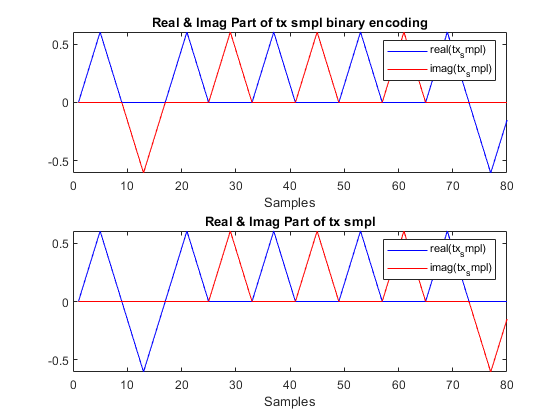

t = 1:80;
subplot(2,1,2)
plot(t,real(tx_smpl_gray),'blue');hold on;
plot(t,imag(tx_smpl_gray),'red');
title("Real & Imag Part of tx smpl");
legend("real(tx_smpl)","imag(tx_smpl)");
xlabel('Samples');

#### **Experiment 5-3)**

**Part 1)**

chnl_delay_in_smpl = 0;
tx_smpl_delayed_bin = [zeros(chnl_delay_in_smpl,1);tx_smpl_bin];
tx_smpl_delayed_gray = [zeros(chnl_delay_in_smpl,1);tx_smpl_gray];

**Part 2)**

chnl_phase_offset = 0;
phase_difference = exp(1i*chnl_phase_offset);
rx_smpl_bin = tx_smpl_delayed_bin * phase_difference;
rx_smpl_gray = tx_smpl_delayed_gray * phase_difference;

**Part 3) AWGN Channel Simulation**

%% Step 1

M = 4;
modulation = 'psk';
[~, Es_avg] = constellation(M, modulation);
Eb = Es_avg / log2(M) ;
N0 = Eb / (10^(/10));
var_noise = N0;

%% Step 2

noise_smpl_bin = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_bin),1);
noise_smpl_gray = sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1) + 1i * sqrt(var_noise)/sqrt(2) * randn(length(rx_smpl_gray),1);
rx_smpl_bin_noise = rx_smpl_bin + noise_smpl_bin;
rx_smpl_gray_noise = rx_smpl_gray + noise_smpl_gray;

Invalid use of operator.

#### Experiment 5-4) Modulation Receiver Implementation

Section 5)

rx_smpl_bin = rx_smpl_bin_noise;
rx_smpl_gray = rx_smpl_gray_noise;
modulation = 'psk';
M = 4;
fs = 10e6;
smpl_per_symbl = 8;
pulse_name = 'triangular';
rx_mode = 2;
[det_sym_idx_bin, rx_sym_bin] = pulse_demodulation(pkt_size,rx_smpl_bin, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);
[det_sym_idx_gray, rx_sym_gray] = pulse_demodulation(pkt_size,rx_smpl_gray, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode, 0);

Section 6)

b_binary = de2bi(0:3,2,'left-msb');
det_bit_bin = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_bin(i,:) = b_binary(det_sym_idx_bin(i)+1,:);
end
det_bit_bin

det_bit_bin =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0



det_bit_gray = zeros(pkt_size,k);
for i=1:pkt_size
    det_bit_gray(i,:) = b_gray(det_sym_idx_gray(i)+1,:);
end
det_bit_gray

det_bit_gray =      0     0
     1     1
     0     0
     0     1
     0     0
     0     1
     0     0
     0     1
     0     0
     1     0


Section 7)

sym_erros_bin = ~(det_sym_idx_bin == sym_idx_bin);
ser_bin = sum(sym_erros_bin)/length(sym_idx_bin);
bit_errors = ~(det_bit_bin == b_tx);
ber_bin = sum(bit_errors,'all')/(pkt_size*k);
ser_bin

ser_bin = 0

ber_bin

ber_bin = 0


sym_erros_gray = ~(det_sym_idx_gray == sym_idx_gray);
ser_gray = sum(sym_erros_gray)/length(sym_idx_gray);
bit_errors = ~(det_bit_gray == b_tx);
ber_gray = sum(bit_errors,'all')/(pkt_size*k);
ser_gray

ser_gray = 0

ber_gray

ber_gray = 0